% Create a genetic regulatory network with two nodes
sim = geneGraph(2);
sim = sim.activation(1,2,3,4)

sim =   geneGraph with properties:

    simulationGraph: [1×1 simGraph]
            digraph: [1×1 digraph]
          highlight: [0 0]


sim = sim.repression(1,1,1.5,4)

sim =   geneGraph with properties:

    simulationGraph: [1×1 simGraph]
            digraph: [1×1 digraph]
          highlight: [0 0 1]


sim = sim.degradation(1,0.2)

sim =   geneGraph with properties:

    simulationGraph: [1×1 simGraph]
            digraph: [1×1 digraph]
          highlight: [0 0 1]


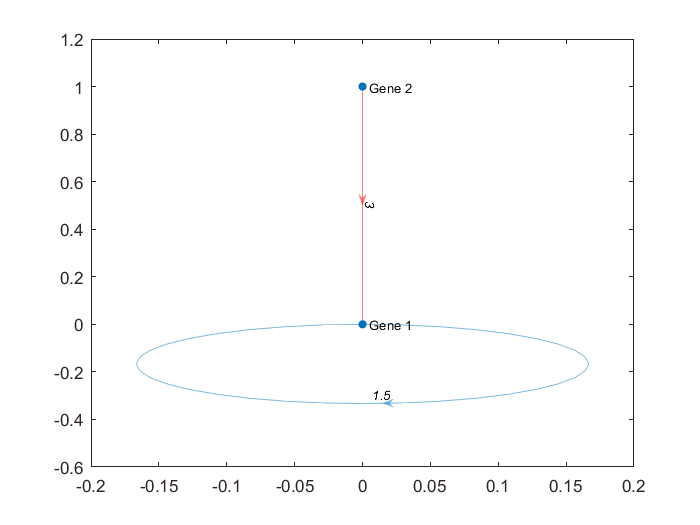

sim = sim.degradation(2,0.3);

sim.showGraph();


% Simulate genetic regulatory network
initialConditions = [10, 15];
noise = 0;
tspan = 100;
[derivativeSeries, results, timePoints] = sim.runRungeKutta(initialConditions, noise, tspan)

Error using simGraph/runRungeKutta
Too many input arguments.

Error in geneGraph/runRungeKutta (line 33)
            [derivativeSeries, results, timePoints] = obj.simulationGraph.runRungeKutta(obj, initialConditions, noise, tspan);


plot(timePoints, derivativeSeries);